**Submitted By**

**Hridya Divakaran : V00970167**

**Sanjana Arora : V00966221 **

Load the Exercise 4 data set. 

clc;
clear;

%loading the dataset
load("Exercise_4_Data.mat")
data_for_processing = a;
index_training = Train_indx;
index_testing = Test_indx;

 Randomly partition the data into training and test sets where the training set represents 25% of the data and the test set represents the remaining 75% of the data. 

% 25 percent of data used for training and its statistics
training_data = data_for_processing(index_training, :);
mean_training_data = mean(training_data);
cov_train = cov(training_data);

% 75 percent of data used for testing and its statistics
testing_data = data_for_processing(index_testing, :);
mean_testing_data = mean(testing_data);
cov_testing_data = cov(testing_data);

**Q4 Use the training data to construct a Principal Component Analysis (PCA) approach to reduce the data to 3 dimensions and apply this dimensionality reduction to the test data.**

dimensions=3;
mean_training_data_repmat = repmat(mean_training_data,length(training_data),1);

% Centralizing the training data
training_data_centralized = training_data - mean_training_data_repmat;

% Finding eigen vectors and values
[vector,values] = eigs(cov_train);


%Keep the number of dimensions desired. Keep the dimensions corresponding to highest eigenvalues.
[ ~ , idx_eig ] = sort( diag(values) , 'descend' );
idx_keep = idx_eig( 1 : dimensions );
w_FLD_train = vector(: , idx_keep );
training_data_dim_reduced = training_data_centralized*w_FLD_train;

% applying the learned projection from training data to the testing data
testing_data_dim_reduced = testing_data*w_FLD_train;


**5. Apply Bayes classification on the dimensionality reduced test data and comment on the classification performance. **

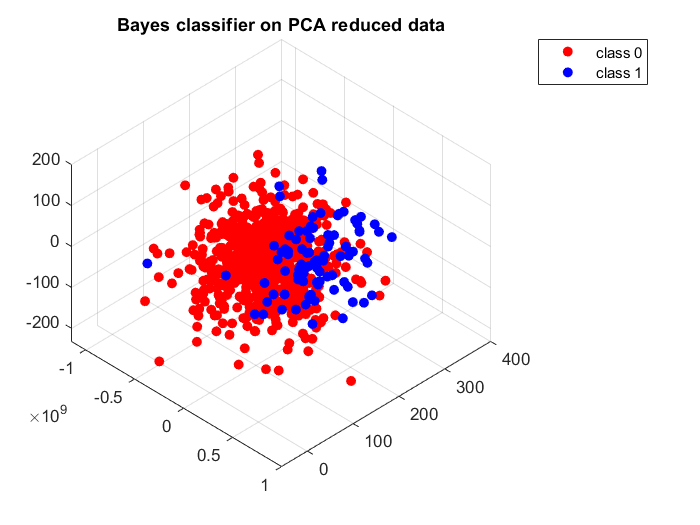

%Let us denote class 0 from the data file as classA and class 1 as classB
traindata_set_class_A = training_data_dim_reduced(find(classes(index_training)==0),:);
traindata_set_class_B = training_data_dim_reduced(find(classes(index_training)==1),:);

mu_class_A = mean(traindata_set_class_A);
mu_class_B = mean(traindata_set_class_B);

sigma_class_A = cov(traindata_set_class_A);
sigma_class_B = cov(traindata_set_class_B);

prioriA = length(traindata_set_class_A) / length(training_data_dim_reduced);
prioriB = length(traindata_set_class_B) / length(training_data_dim_reduced);

% Calculate the discriminant function values of a data point for classes 0 and 1 respectively
gk_A = discriminant_fn(mu_class_A', sigma_class_A, prioriA, testing_data_dim_reduced);
gk_B = discriminant_fn(mu_class_B', sigma_class_B, prioriB, testing_data_dim_reduced);

class_A_points = find(gk_A >= gk_B);
class_B_points = find(gk_B > gk_A);

% Array containing data points for each class
result_A = testing_data_dim_reduced(class_A_points, :);
result_B = testing_data_dim_reduced(class_B_points, :);

% Plot the classes 0, 1 regions
scatter3(result_A(:, 1), result_A(:, 2), result_A(:, 3), 'filled', 'red')
hold on;
scatter3(result_B(:, 1), result_B(:, 2), result_B(:, 3), 'filled', 'blue')
title('Bayes classifier on PCA reduced data')
legend('class 0', 'class 1')
view([45, 45]);
hold off;

% Output the predicted labels for testing data points
label_matrix = 2 * ones(1,length(testing_data_dim_reduced))';
label_matrix(class_A_points, :) = 0;
label_matrix(class_B_points, :) = 1;
result_label = label_matrix;

% Calculate the performance of Bayes calssifier based on PCA
wrong_classifications_PCA = sum(result_label ~= classes(index_testing)')

wrong_classifications_PCA = 346

**Q5 Discussion**

The number of wrongly classified samples in PCA are very high. It is attributed to the fact that PCA is a good method for dimensionality reduction, however, not an ideal method for performing classification of the data. PCA does not project the data onto a direction that could provide good classification information and hence, the number of wrongly classified samples is higher for PCA.

**6. Discuss whether PCA is a correct approach to apply for addressing classification problems and present clear arguments as to why (or why not).**

Answer: PCA is a good approach for dimensionality reduction but it is not a correct approach for classification problems because PCA has no knowledge about the classes and uses variance of the features to determine the reduced number of features. PCA just projects the data onto the eigen vector e1 as shown in the figure below and that eigen vector does not provide the right direction for classifying the data. Therefore, bayes classifier is not able to discriminate between the two classes correctly.

                                                                  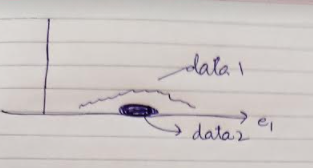

PCA looks for properties in data that show as much variation across classes as possible to build the principal component space. In order to reduce the dimension of the dataset, PCA chooses those eigenvectors that have more variance and discard those with less variance. However, eigen vectors derived from variance of fearures are not able to identify the feature that includes the valuable information about the classes and thus, PCA is unable to perform correct classification. 

function g_x = discriminant_fn(mu,sigma,prior_prob,x) 
    w1 = (-1/2)*inv(sigma);
    
    w2 = inv(sigma)*mu;
    
    w3 = (-1/2)*mu'*inv(sigma)*mu - (1/2)*log(det(sigma)) + log(prior_prob);
        
    g_x = sum((x*w1.').*x,2).' + w2'*x' + w3;
    

end 

